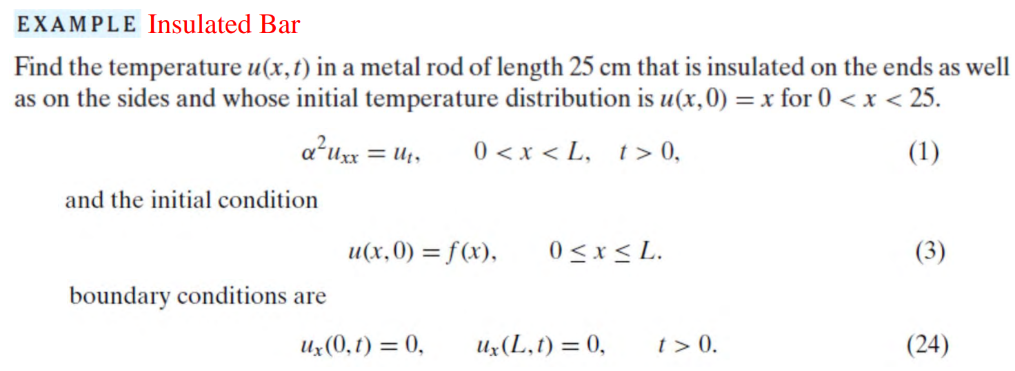

**Separation part**

clear 
clf
clc
syms x t u(x,t) L D
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

Dx = diff(u,x);
BC0 = Dx(0,t) == 0

$$BC0 = \left({\left(\frac{\partial }{\partial x}u\left(x,t\right)\right)|}_{x=0}\right)=0$$

BCL = Dx(L,t) == 0

$$BCL = \frac{\partial }{\partial L}u\left(L,t\right)=0$$

**Substitution**

syms T(t) X(x)
SepVar = subs(HeatEq,u(x,t),X(x)*T(t));
SepVar = SepVar/(D*X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

var = children(SepVar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX)

$$X(x, lambda) = C_{1}\,\cos\left(\lambda \,x\right)-C_{2}\,\sin\left(\lambda \,x\right)$$

Dx(x,lambda) =diff(X,x)

$$Dx(x, lambda) = -C_{2}\,\lambda \,\cos\left(\lambda \,x\right)-C_{1}\,\lambda \,\sin\left(\lambda \,x\right)$$

syms C2
c2 = solve(-Dx(0,1) == 0,C2)

$$c2 = 0$$

xL(x,lambda) = subs(X,C2,c2)

$$xL(x, lambda) = C_{1}\,\cos\left(\lambda \,x\right)$$

DxL(x,lambda) = diff(xL,x)

$$DxL(x, lambda) = -C_{1}\,\lambda \,\sin\left(\lambda \,x\right)$$

sln = DxL(L,lambda) == 0

$$sln = -C_{1}\,\lambda \,\sin\left(L\,\lambda \right)=0$$

**Solve for lambda**

[lambda,parameters,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{L}$$

syms a_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
cosX(x,n) = subs(xL(x,lambda),[lambda,sym('C1')],[lambda,a_n]);
ustruct(x,t,n) = collect(cosX(x,n)*expT(t,n),["cos" "exp"])

$$ustruct(x, t, n) = a_{n}\,\cos\left(\frac{\pi \,n\,x}{L}\right)\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}$$

**Fourier series part**

syms x t n a(n) phi(x)
assume(n,"integer")
L = 25

L = 25

phi(x) = x;
D = 1

D = 1

N = 20

N = 20

ft0 = subs(ustruct(x,0,n),sym(["a_n" "L"]),[1 L])

$$ft0 = \cos\left(\frac{\pi \,n\,x}{25}\right)$$

a0 = simplify(2/L*int(phi(x),x,[0 L]))

$$a0 = 25$$

a(n) = simplify(2/L*int(phi(x)*ft0,x,[0 L]))

$$a(n) = -\frac{25\,{\left(-1\right)}^{n+1}\,{\left({\left(-1\right)}^{n}-1\right)}^{2}}{n^{2}\,\pi^{2}}$$

heatStruct = ustruct

$$heatStruct(x, t, n) = a_{n}\,\cos\left(\frac{\pi \,n\,x}{L}\right)\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}$$

heatstructEmb(x,t,n) = subs(heatStruct,sym(["a_n" "L" "D"]),[a L D]);

**Heat Solution**

Solution = symsum(heatstructEmb,n,1,inf)

$$Solution(x, t) = -\frac{25\,\left(\sum_{n=1}^{\infty }\frac{{\left(-1\right)}^{n+1}\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{625}}\,\cos\left(\frac{\pi \,n\,x}{25}\right)\,{\left({\left(-1\right)}^{n}-1\right)}^{2}}{n^{2}}\right)}{\pi^{2}}$$

heatSolN = a0/2+simplify(symsum(heatstructEmb,n,1,N))

$$heatSolN(x, t) = \begin{array}{l} \frac{25}{2}-\frac{33870234994596\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{25}}\,\cos\left(\frac{\pi \,x}{5}\right)+3763359443844\,{\mathrm{e}}^{-\frac{\sigma_{1}}{25}}\,\cos\left(\frac{3\,\pi \,x}{5}\right)+846755874864900\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{625}}\,\cos\left(\frac{\pi \,x}{25}\right)+94083986096100\,{\mathrm{e}}^{-\frac{\sigma_{1}}{625}}\,\cos\left(\frac{3\,\pi \,x}{25}\right)+17280732140100\,{\mathrm{e}}^{-\frac{49\,t\,\pi^{2}}{625}}\,\cos\left(\frac{7\,\pi \,x}{25}\right)+10453776232900\,{\mathrm{e}}^{-\frac{81\,t\,\pi^{2}}{625}}\,\cos\left(\frac{9\,\pi \,x}{25}\right)+6997982436900\,{\mathrm{e}}^{-\frac{121\,t\,\pi^{2}}{625}}\,\cos\left(\frac{11\,\pi \,x}{25}\right)+5010389792100\,{\mathrm{e}}^{-\frac{169\,t\,\pi^{2}}{625}}\,\cos\left(\frac{13\,\pi \,x}{25}\right)+2929951124100\,{\mathrm{e}}^{-\frac{289\,t\,\pi^{2}}{625}}\,\cos\left(\frac{17\,\pi \,x}{25}\right)+2345584140900\,{\mathrm{e}}^{-\frac{361\,t\,\pi^{2}}{625}}\,\cos\left(\frac{19\,\pi \,x}{25}\right)}{8467558748649\,\pi^{2}}\\ \mathrm{where}\\ \sigma_{1}=9\,t\,\pi^{2} \end{array}$$

**3D plot**

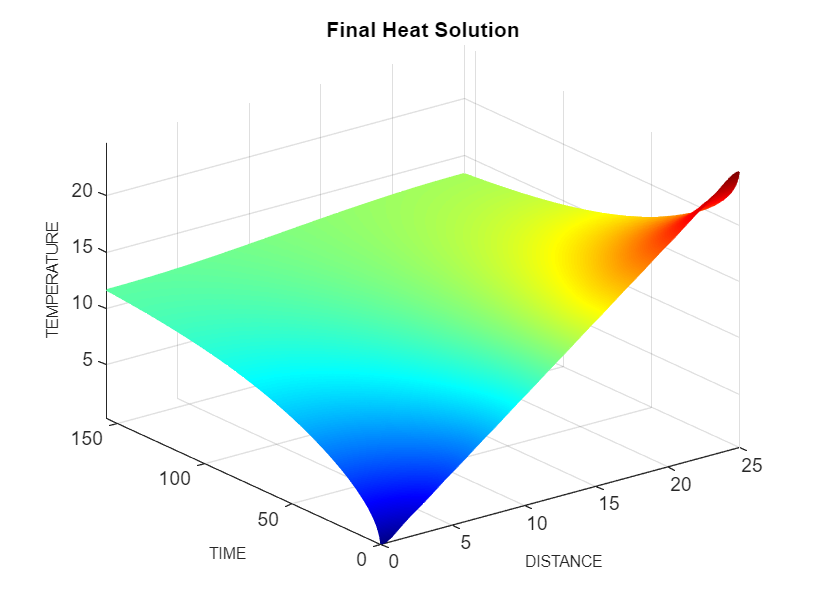

figure
colormap jet
tau = L^2/D;
fsurf(heatSolN,[0 L 0 tau/4],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('TEMPERATURE','FontSize',8)

**Heat profile at different times**

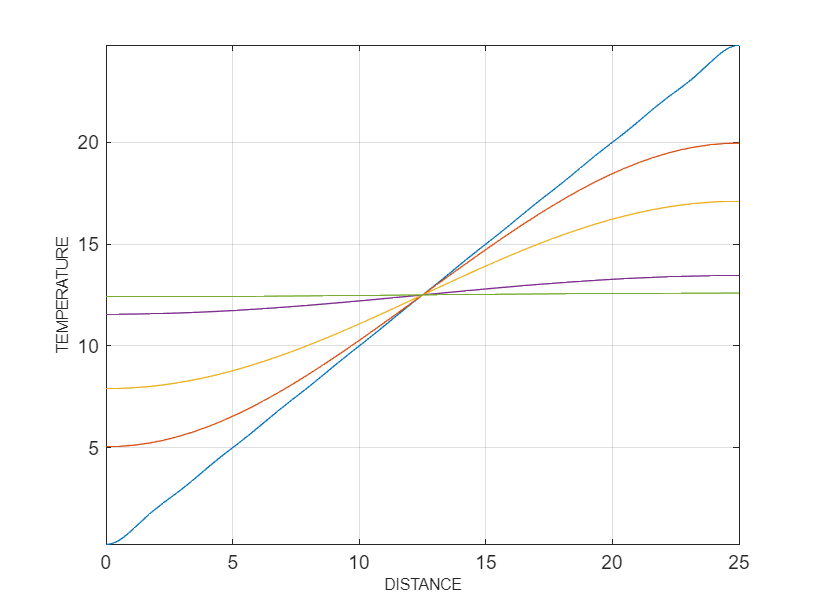

clf 
tm = [0 20 50 150 300];
for i = 1:length(tm)
    sn = matlabFunction(heatSolN(x,tm(i)));
    fplot(sn,[0 L])
    grid on, hold on
end
xlabel('DISTANCE','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)

**Heat profile at various distances**

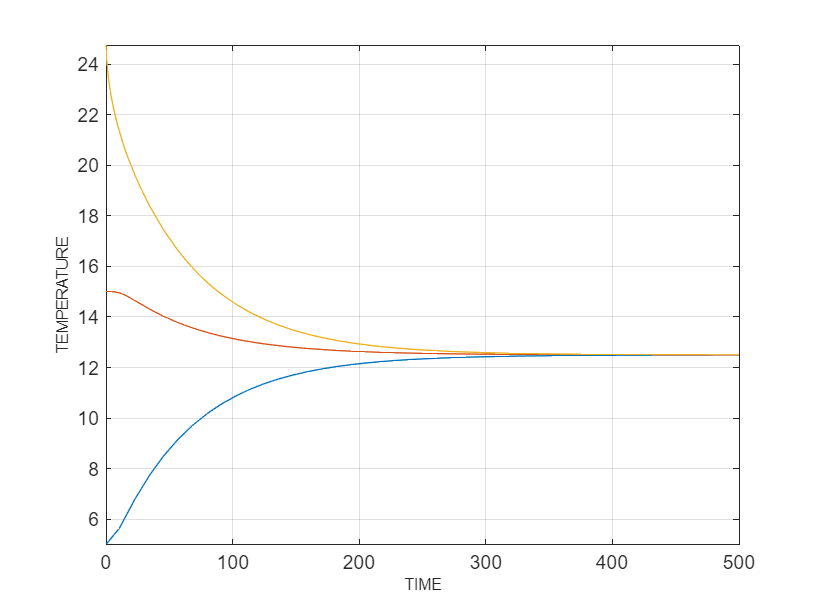

clf
dst = [5 15 25];
for i = 1:length(dst)
    sn = matlabFunction(heatSolN(dst(i),t));
    fplot(sn, [0 500])
    grid on , hold on
end
xlabel('TIME','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)